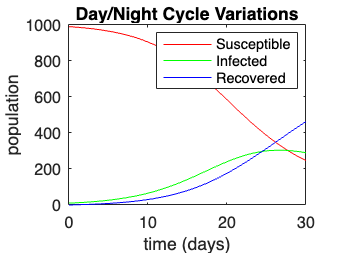

%Periodic Variation of Transmission Rate
A = 5;
omega = [2*pi,2*pi*(100/365)];
h = 0.1;
b0 = 0.3;
gamma = 0.1;
T0 = 0;
T = 30;
S0 = 990;
I0 = 10;
R0 = 0;
N = S0 + I0 + R0;
DayNight = modelSIR_P4(S0,I0,R0,T0,T,h,b0,A,omega(1),gamma);


plot(DayNight(1,:),DayNight(2,:),'r',DayNight(1,:),DayNight(3,:),'g',DayNight(1,:),DayNight(4,:),'b');
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Day/Night Cycle Variations');

%frequency
f = (1/T)*(0:(N/2));
% FFT for Susceptible Pop
fftSus = fft(DayNight(2,:));
fftSusabs = abs(fftSus/T);
P1 = fftSusabs(1:T/2+1);
P1(2:end-1) = 2*P1(2:end-1);
% FFT for Infected
fftInf = fft(DayNight(3,:));
fftInfabs = abs(fftInf/T);
P3 = fftInfabs(1:T/2+1);
P3(2:end-1) = 2*P3(2:end-1);
% FFT for Recovered
fftRec = fft(DayNight(4,:));
fftRecabs = abs(fftRec/T);
P5 = fftRecabs(1:T/2+1);
P5(2:end-1) = 2*P5(2:end-1);
% Spectrum plot for infected
plot(f,P3)

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('f(Hz)');
ylabel('Fast Fourier Transform');
title('Spectrum of Infected (Day/Night Cycle');

Weekly = modelSIR_P4(S0,I0,R0,T0,T,h,b0,A,omega(2),gamma);


plot(Weekly(1,:),Weekly(2,:),'r',Weekly(1,:),Weekly(3,:),'g',Weekly(1,:),Weekly(4,:),'b');
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Weekly Variations');

%frequency
f = (1/T)*(0:(N/2));
% FFT for Susceptible Pop
fftSus2 = fft(Weekly(2,:));
fftSusabs2 = abs(fftSus2/T);
P2 = fftSusabs2(1:T/2+1);
P2(2:end-1) = 2*P2(2:end-1);
% FFT for Infected
fftInf2 = fft(Weekly(3,:));
fftInfabs2 = abs(fftInf2/T);
P4 = fftInfabs2(1:T/2+1);
P4(2:end-1) = 2*P4(2:end-1);
% FFT for Recovered
fftRec2 = fft(Weekly(4,:));
fftRecabs2 = abs(fftRec2/T);
P6 = fftRecabs2(1:T/2+1);
P6(2:end-1) = 2*P6(2:end-1);
% Spectrum plot for infected
plot(f,P4)
xlabel('f(Hz)');
ylabel('Fast Fourier Transform');
title('Spectrum of Infected (Weekly Variations)');